# Pendulum exercise

clear all
close all
clc

% Initialize simulation variables
theta_setpoint = 1;  % [rad] set-point for the pendulum angular position
debug_mode = 0;      % debug mode flag (1=debug, 0=normal). If the debug mode is activated the controller plant becomes a pure double integrator
manual_control_flag = 1;    % flag to switch from manual to ADRC control (1=manual, 0=adrc)
u_manual = 0;   % [Nm] manual control action (motor torque), it is applied only if manual control is activated


% Simulation settings
Tsim = 10;
rel_tol= 1e-6;

% Initialize pendulum variables
M = 0.4;    % [kg] mass of the pendulum tip
l = 0.3;    % [m] length of the pendulum rod
c = 0.1;    % viscous friction coefficient
g = 9.81;    % [m/s^2] acceleration due to gravity

% Sensor noise
pow = 0;
Ts = 1e-3;

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 


% Disturbance settings
m_e = 0.2;     % [kg] eccentric mass
r_e = 0.02;    % [m] eccentric radius
omega_m = 20; % [rad/s] eccentric shaft angular velocity
Fc = m_e*r_e*omega_m^2;     % [N] centrifugal force
disturbance_flag = 0;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)
T_dist = 5;     % [s] time at which the motor is turned on


% ADRC tuning
% Desired closed-loop response characteristics
T_settle = 2;    %   [s] settling time 98%
xi = 1;     % desired closed-loop damping
omega_c = 6/T_settle;   % [rad/s] desired closed-loop bandwidth

% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
omega_o = 10*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


## Debug

First we perform a debug to be sure that we have implemented correctly the Extended state observer (ESO) and the state-feedback controller.

Thus, we enable the debug mode and the controlled plant becomes a pure double integrator. This means that the model implemented in the ESO perfectly matches the model of the plant. So, we are expecting that the closed-loop response perfectly matches the one we have imposed when designing the state-feedback controller.

To verify this we plot the set-point following closed-loop response and we compare it with the theoretical one that we have considered to tune the gains of the state-feedback controller.

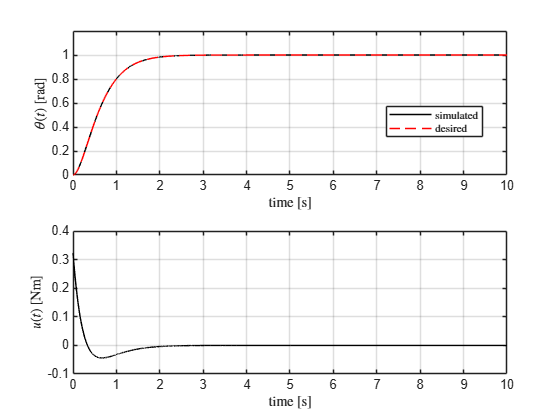

debug_mode = 1;      % debug mode flag (1=debug, 0=normal)

% Enable ADRC controller
manual_control_flag = 0;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

We notice that the simulated response perfectly matches the desired one. This means that we have implemented everything in the right way.

We check also the states reconstructed by the ESO and we compare them with the real one of the plant.

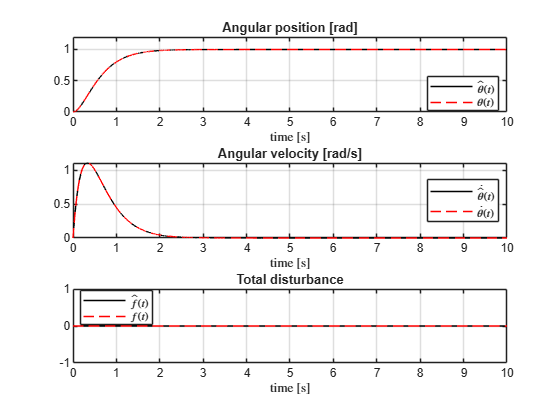

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

We see that the states estimated by the ESO perfectly match those of the double integrator plant.

Note that the total disturbance term is equal to zero, this is because the model implemented in the ESO (the enforced plant) perfectly matches the controlled plant.

However, this was only for debug purposes. So now we considered the true plant.

First, to check if we have implemented the pendulum model correctly we perform an open-loop simulation by letting start the pendulum from an initial angle different from zero and we plot the response.

Note that at time 5s the sinusoidal disturbance is activated by turning on the motor with the eccentric mass placed at the tip of the pendulum.

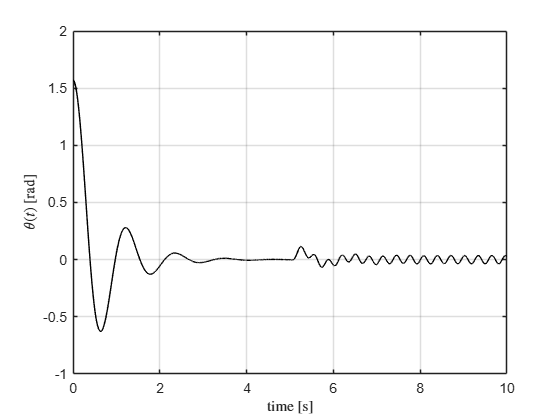

debug_mode = 0;      % debug mode flag (1=debug, 0=normal)
manual_control_flag = 1; % flag to switch from manual to adrc control (1=manual, 0=adrc)

theta_init = pi/2; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

disturbance_flag = 1;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t_ol = simout.tout;
theta_ol = simout.yout{1}.Values.Data;

% Plot the results of the simulation
figure;
plot(t_ol, theta_ol, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;

The behavior of the model is sensible, if we let the pandulum fall freely in oscillates and then it settles in vertical position.

Then, to check that the input part of the pendulum model is correct we give as input the torque necessary to keep the pendulum steady in the initial conditions and we check the results.

Not that here the sinusoidal disturbance is turned off.

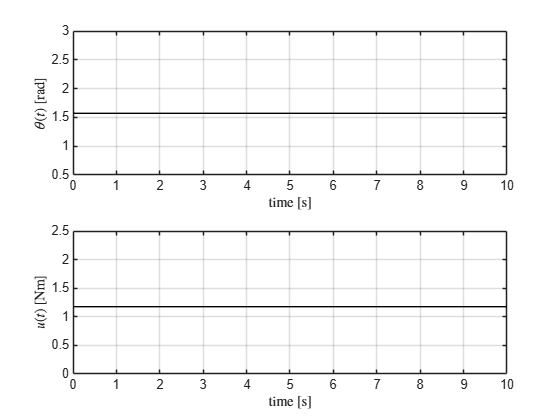

u_manual = M*g*l;
disturbance_flag = 0;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

The result matches the expectation.

To further verify the model, we initialize the pendulum to its stable vertical position end we check the effect of applying a motor torque.

Also here the sinusoidal disturbance is turned off.

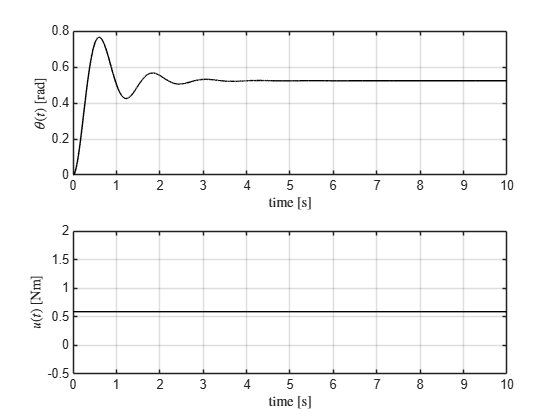

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

u_manual = (M*g*l)/2;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(2,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

As expected, by applying a motor torque the pendulum departs from its equilibrium position and settles to an angle different from zero.

We also check the states estimated by the ESO.

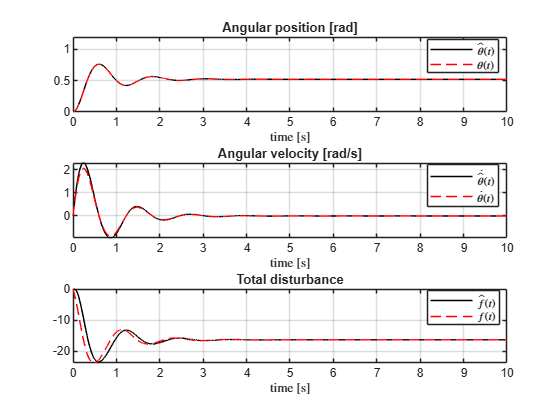

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

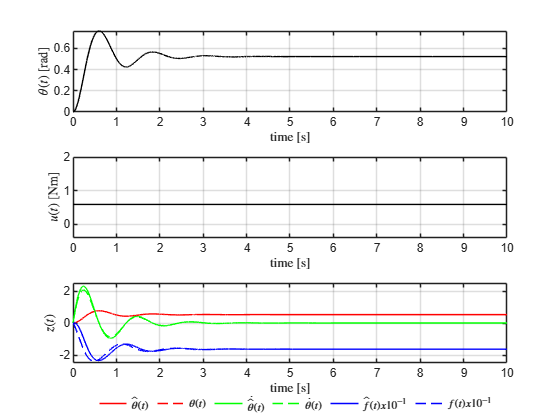

figure;
subplot(3,1,1)
plot(t, theta, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on;
subplot(3,1,2)
plot(t, u, 'k');
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-2.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) x 10^{-1}$', '$f (t) x 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

Note that now the total disturbance term is different from zero because the actual plant differes from the ideal double integrator plant.

However, the ESO is doing a good job in properly estimating the states of the actual plant.

## Closed-loop simulation

### Nominal case

Now we perform a closed-loop simulation by enabling the ADRC controller.

The pendulum must reach the set-point angle of 1 rad with a settling time at 10% of the setpoint in less than 5 seconds.

The effect of the sinusoidal disturbance on the angle of the pendulum must remain within 10% of the setpoint.

The peak-to-peak amplitude of the oscillations on the motor torque must be remain within 1 [Nm] to avoid damages to the motorized joint.

Find a suitable value of keo to satisy the control specifications.

% Pendulum initial conditions
theta_init = 0; % [rad] initial angle
theta_dot_init = 0;   % [rad/s] initial angular velocity 

% Enable ADRC controller
manual_control_flag = 0;

disturbance_flag = 1;   % flag to turn on the motor with the eccentric shaft (1=on, 0=off)

% ADRC controller setup
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
keo =20

keo = 20

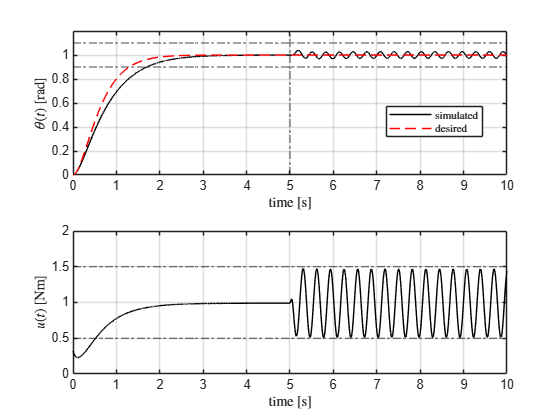

omega_o = keo*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

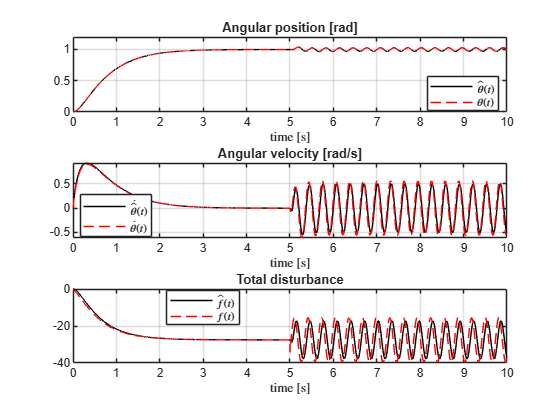

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

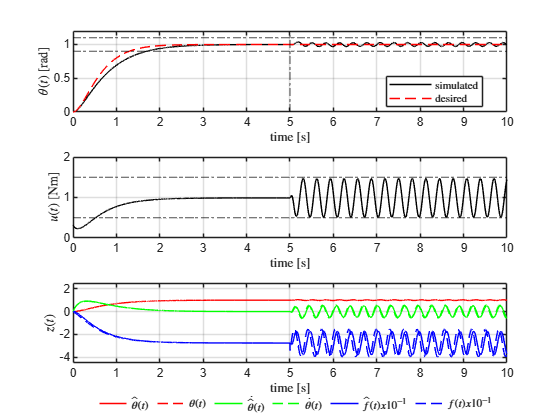

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) x 10^{-1}$', '$f (t) x 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

We see that with the tuning we have performed the specifications are met.

### Measurement noise

The sensor that measures the angular dispacement of the pendulum is affected by measurement noise.

Thus we must consider it for our design.

Remember that the peak-to-peak amplitude of the oscillations on the motor torque must be remain within 1 [Nm] to avoid damages to the motorized joint.

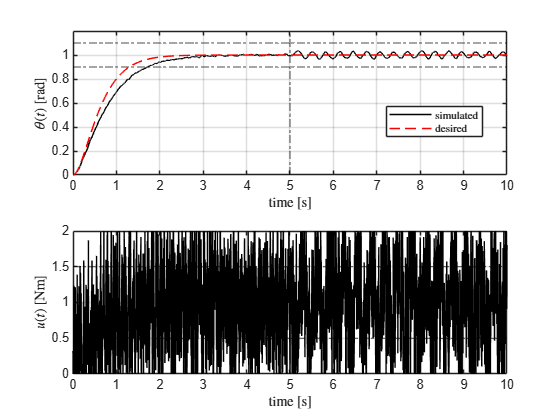

% Sensor noise
pow = 1e-6;

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

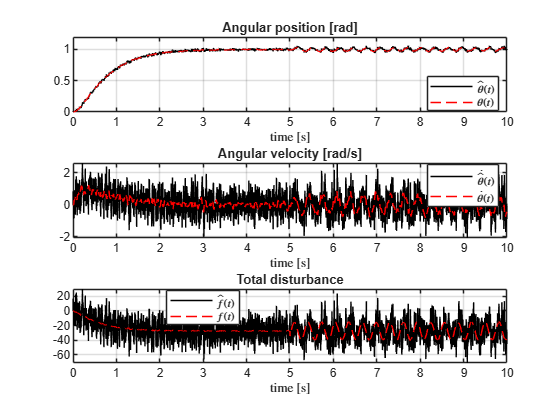

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

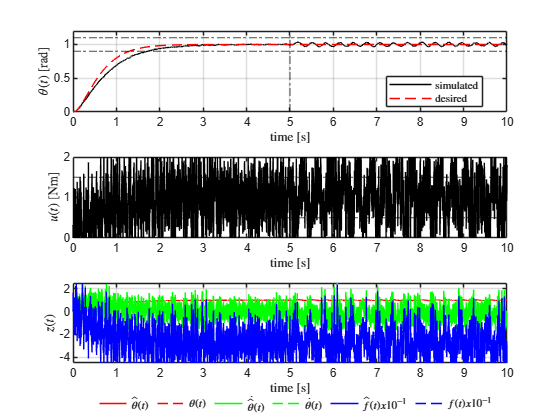

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;
subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) x 10^{-1}$', '$f (t) x 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

We see that the noise level on the motor torque exceeds the limits imposed by the specification. 

Thus we adjust the observer bandwidth to cope with the noise issue.

keo =7

keo = 7

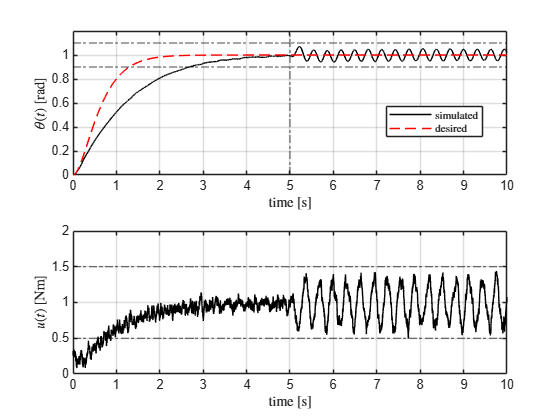

omega_o = keo*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];

% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

theta_nom = theta;
t_nom = t;

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

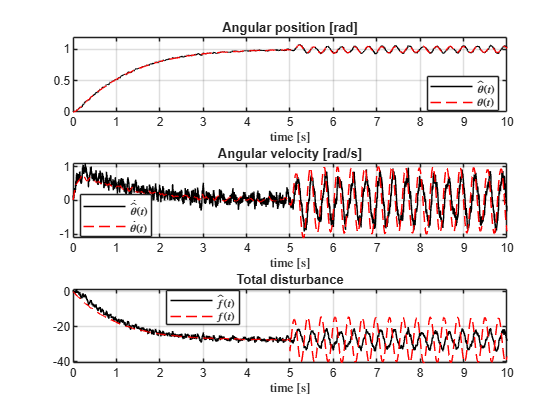

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

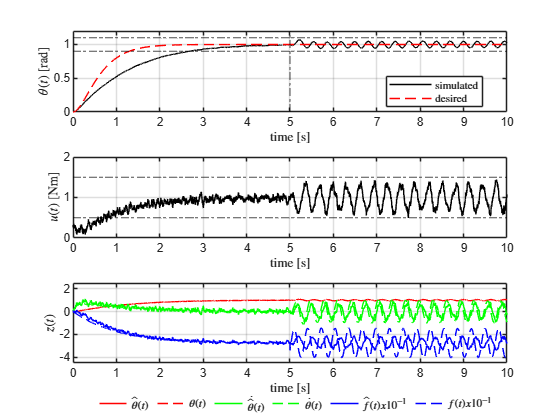

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(5, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) x 10^{-1}$', '$f (t) x 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it

Now we see that the limit on the noise is satisfyed.

The behavior of the controlled variable departs from the designed one, however the control specification is met.

Thus we decide that this solution can be a good trade-off between performance and noise on the control action.

Retuning for faster set-point tracking.

We want the controlled variable to settle within 10% of the set-point in less than 2 seconds.

The other control specifications remain unchanged.

Tune the ADRC controller to satisfy this new control specification for the set-point tracking task.

% ADRC tuning
% Desired closed-loop response characteristics
T_settle = 1.5;    %   [s] settling time 98%
xi = 1;     % desired closed-loop damping
omega_c = 6/T_settle;   % [rad/s] desired closed-loop bandwidth
b0 = 1/(M*l^2);
k1 = omega_c^2;
k2 = 2*xi*omega_c;
keo =5

keo = 5

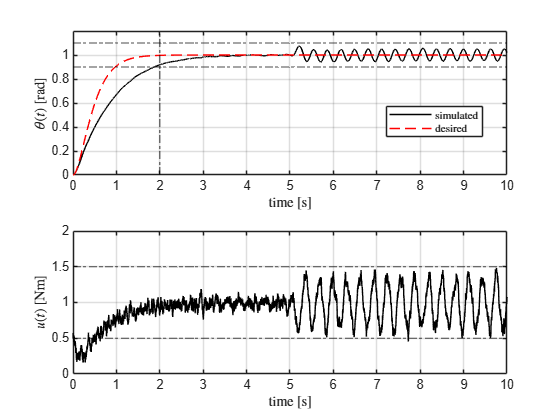

omega_o = keo*omega_c;
l1 = 3*omega_o;
l2 = 3*omega_o^2;
l3 = omega_o^3;
L = [ l1 ;
      l2 ;
      l3 ];
A = [0  1  0;
     0  0  1;
     0  0  0];
B = [  0;
       b0;
       0  ];
C = [1 0 0];


% Perform the simulation
simout = sim("pendulum_adrc_sim.slx");
t = simout.tout;
theta = simout.yout{1}.Values.Data;
theta_hat = simout.yout{2}.Values.Data;
theta_hat_dot = simout.yout{3}.Values.Data;
f_hat = simout.yout{4}.Values.Data;
theta_dot = simout.yout{5}.Values.Data;
f = simout.yout{6}.Values.Data;
u = simout.yout{7}.Values.Data;

% Expected response
s = tf('s');
Ps = (omega_c^2)/(s^2+2*xi*omega_c*s+omega_c^2);
t_step = 0:0.01:10;
[y_step,~] = step(Ps,t_step);

% Plot the results of the simulation
figure;
subplot(2,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(2, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(2,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

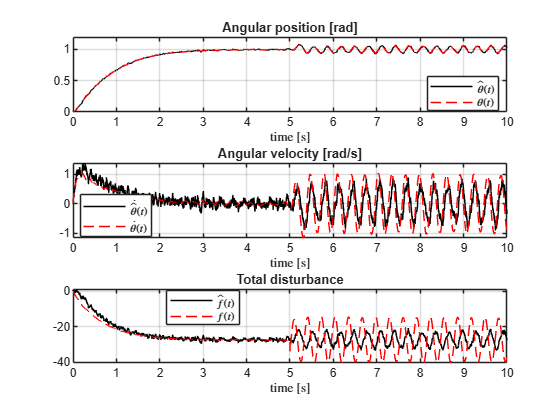

figure;
subplot(3,1,1)
p1 = plot(t, theta_hat, 'k');
hold on 
p2 = plot(t, theta, '--r');
legend([p1 p2], {'$\hat{\theta} (t)$', '$\theta (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on
ylim([0 1.2])
title('Angular position [rad]')

subplot(3,1,2)
p1 = plot(t, theta_hat_dot, 'k');
hold on 
p2 = plot(t, theta_dot, '--r');
legend([p1 p2], {'$\dot{\hat{\theta}} (t)$', '$\dot{\theta} (t)$'}, 'Location', 'best', 'Interpreter', 'latex')
xlabel('time [s]','Interpreter','latex');
grid on;
title('Angular velocity [rad/s]')

subplot(3,1,3)
p1 = plot(t, f_hat, 'k');
hold on 
p2 = plot(t, f, '--r');
legend([p1 p2], {'$\hat{f}(t)$', '$f(t)$'}, 'Location', 'best', 'Interpreter', 'latex')
grid on
title('Total disturbance')
xlabel('time [s]','Interpreter','latex');

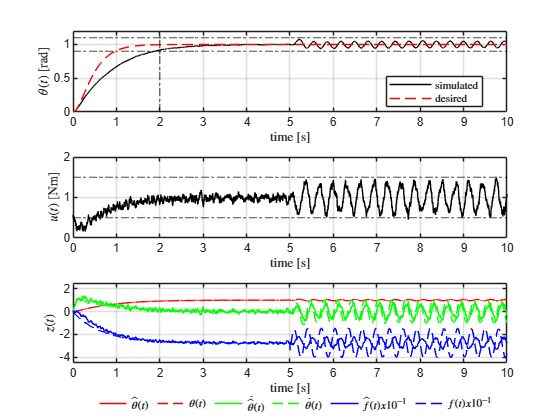

% Plot the results of the simulation
figure;
subplot(3,1,1)
p1 = plot(t, theta, 'k'); hold on
p2 = plot(t_step, y_step, '--r');
yline(0.9, '-.k', 'LineWidth', 0.75);
yline(1.1, '-.k', 'LineWidth', 0.75);
xline(2, '-.k', 'LineWidth', 0.75);
xlabel('time [s]','Interpreter','latex');
ylabel('$\theta (t)$ [rad]','Interpreter','latex');
grid on
legend([p1 p2], {'simulated', 'desired'}, 'Location', 'best', 'Interpreter', 'latex')
ylim([0 1.2])

subplot(3,1,2)
plot(t, u, 'k');
yline(0.5, '-.k', 'LineWidth', 0.75);
yline(1.5, '-.k', 'LineWidth', 0.75);
ylim([0 2])
xlabel('time [s]','Interpreter','latex');
ylabel('$u (t)$ [Nm]','Interpreter','latex');
grid on;

subplot(3,1,3)
p1 = plot(t, theta_hat, 'r');
hold on
grid on
p2 = plot(t, theta, '--r');
p3 = plot(t, theta_hat_dot, 'g');
p4 = plot(t, theta_dot, '--g');
p5 = plot(t, f_hat*0.1, 'b');
p6 = plot(t, f*0.1, '--b');
xlabel('time [s]','Interpreter','latex');
ylabel('$z (t)$','Interpreter','latex');
ylim([-4.5 2.5])
% Create a small invisible axes spanning the figure width for the legend
left = 0.13;           % default left margin for MATLAB figures
width = 0.775;         % default width for axes
legendHeight = 0.08;   % adjust height of legend area
bottom = 0.01;         % distance from bottom of figure

lgAx = axes('Position',[left bottom width legendHeight],'Visible','off');

% Create legend in that axes; use the line handles from the subplot
lgd = legend(lgAx, [p1 p2 p3 p4 p5 p6], ...
    {'$\hat{\theta} (t)$', '$\theta (t)$', '$\dot{\hat{\theta}} (t)$', ...
     '$\dot{\theta} (t)$', '$\hat{f} (t) x 10^{-1}$', '$f (t) x 10^{-1}$'}, ...
    'Orientation','horizontal','Interpreter','latex','Box','off');

% Shorten the legend line tokens and tweak spacing
lgd.FontSize = 8;
lgd.ItemTokenSize = 20;      % shorten the line segment (points)
lgd.Position(2) = bottom;    % ensure it stays where we placed it